# Longitudinal Vehicle - Test Case

## DriveAxle - Input Torque to Axle

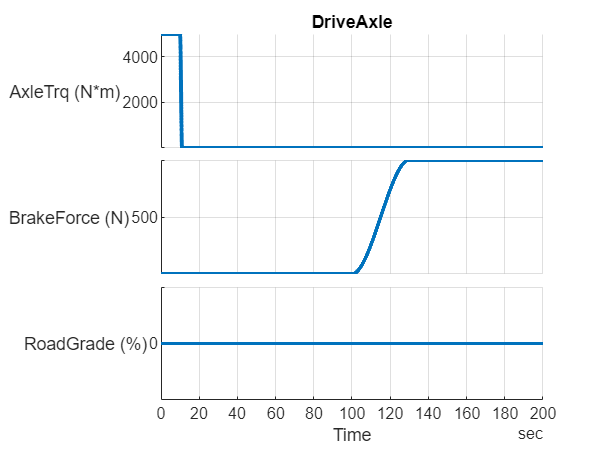

mdl = "Vehicle1D_harness_model";
if not(bdIsLoaded(mdl))
  load_system(mdl)
end

Vehicle1D_harness_setup

vehSigBuilder = Vehicle1D_InputSignalBuilder;
vehSigBuilder.Plot_tf = true;

inpData = DriveAxle(vehSigBuilder, ...
            InitialVehicleSpeed_kph = 50, ...
            RoadGrade_Const_pct = 0, ...
            AxleTorque_1_Nm = 5000, ...
            AxleTorque_2_Nm = 0, ...
            AxleTorque_3_Nm = 0, ...
            BrakeForce_1_N = 0, ...
            BrakeForce_2_N = 1000, ...
            AxleTorqueChange_1_StartTime = seconds(10), ...
            AxleTorqueChange_1_EndTime = seconds(10 + 1), ...
            AxleTorqueChange_2_StartTime = seconds(11 + 9), ...
            AxleTorqueChange_2_EndTime = seconds(20 + 1), ...
            BrakeForceChange_1_StartTime = seconds(100), ...
            BrakeForceChange_1_EndTime = seconds(100 + 30), ...
            StopTime = seconds(30 + 170) );

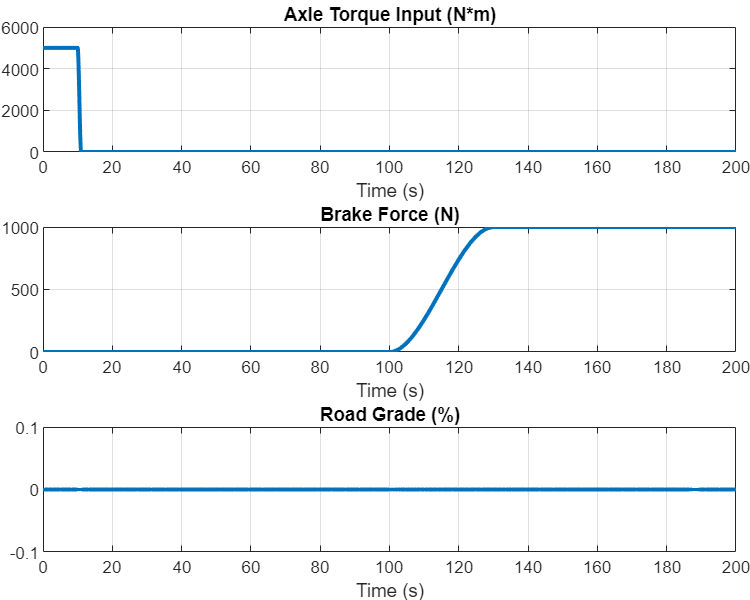

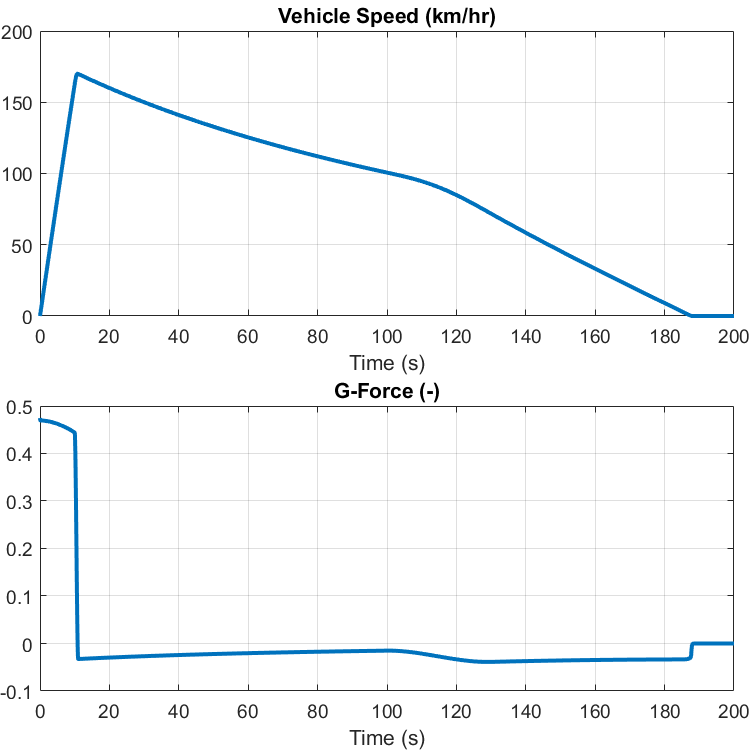

simIn = Simulink.SimulationInput(mdl);
simIn = setVariable(simIn, "vehicle_InputSignals", inpData.Signals);
simIn = setVariable(simIn, "vehicle_InputBus", inpData.Bus);
simIn = setModelParameter(simIn, "StopTime",num2str(inpData.Options.StopTime_s));

simOut = sim(simIn);

Vehicle1D_plot_results(simOut.logsout);

*Copyright 2020-2022 The Mathworks, Inc.*